% ============================================================
% TASK 5 - TESTING THE SINGLE-PHOTON SCANNING CAMERA
%
% Illuminated object / star field
%          ↓
%       Telescope
%          ↓
%   Beam-steering mirror
%          ↓
%     Single-mode fibre
%          ↓
%      SPCM-AQRH
%          ↓
%     Photon counts
%
% The beam-steering mirror scans the image across the fibre.
%
% At each mirror position:
%   1. Move the mirror
%   2. Allow the mirror to settle
%   3. Measure photon counts
%   4. Store the count at that scan position
%
% ============================================================

clear;
clc;
close all;


%% ============================================================
% 1. SCAN PARAMETERS
% ============================================================

% Number of scan positions

MAP_WIDTH  = 100;
MAP_HEIGHT = 100;


% ------------------------------------------------------------
% These are currently just array indices.
%
% Later, these will be linked to the actual MR-E-3 mirror
% angles / positions.
% ------------------------------------------------------------

scanX = 1:MAP_WIDTH;
scanY = 1:MAP_HEIGHT;


%% ============================================================
% 2. TELESCOPE / FIBRE PARAMETERS
% ============================================================

% Telescope effective focal length

focalLength = 6459;       % mm


% Fibre / effective sampling diameter

fibreSize = 4.2e-3;       % mm
                          % 4.2 micrometres


% Calculate angular sampling size

SPC_FOV_arcsec = ...
    (fibreSize / focalLength) * 206265;


% For this initial model, assume one scan position
% corresponds to one effective fibre sampling position.

STAR_PIXEL_SIZE_arcsec = SPC_FOV_arcsec;


fprintf('SPC angular sampling size = %.4f arcsec\n', ...
    SPC_FOV_arcsec);

SPC angular sampling size = 0.1341 arcsec




%% ============================================================
% 3. CREATE OUTPUT SPC FRAME
% ============================================================

% Each element represents one mirror scan position.
%
% The value stored here will eventually be the number of
% photons detected by the SPCM at that position.

SPC_frame = zeros(MAP_HEIGHT, MAP_WIDTH);


%% ============================================================
% 4. DETECTOR / MEASUREMENT SETTINGS
% ============================================================

% Integration time for each measurement.
%
% This is the amount of time over which photon counts
% will eventually be collected.
%
% Set this when the detector/DAQ setup is known.

integrationTime = [];      % seconds


% ------------------------------------------------------------
% PLACEHOLDER FOR DETECTOR INITIALISATION
% ------------------------------------------------------------
%
% Insert detector / NI 6553 initialisation code here.
%
% Example:
%
% detector = ...
%
% ============================================================


%% ============================================================
% 5. BEAM-STEERING MIRROR SCAN
% ============================================================

for iy = 1:length(scanY)

    for ix = 1:length(scanX)


        %% ----------------------------------------------------
        % CURRENT SCAN POSITION
        % -----------------------------------------------------

        mirrorX = scanX(ix);
        mirrorY = scanY(iy);


        %% ----------------------------------------------------
        % MOVE MR-E-3 MIRROR
        % -----------------------------------------------------
        %
        % INSERT YOUR MIRROR MOVEMENT CODE HERE
        %
        % The variables mirrorX and mirrorY represent the
        % current scan position.
        %
        % Your code will eventually convert these positions
        % into the appropriate MR-E-3 commands / angles.
        %
        %
        % >>>>>>>>>>> INSERT MIRROR CODE HERE <<<<<<<<<<<<<
        %
        %
        % Example structure only:
        %
        % moveMirror(mirrorX, mirrorY);
        %
        % DO NOT use this example unless it matches your
        % actual mirror-control software.
        %
        % ----------------------------------------------------


        %% ----------------------------------------------------
        % WAIT FOR MIRROR TO SETTLE
        % -----------------------------------------------------
        %
        % INSERT SETTLING DELAY HERE
        %
        % Example:
        %
        % pause(0.1);
        %
        % The correct value should be determined experimentally.
        %
        %
        % >>>>>>>>>>> INSERT SETTLING CODE HERE <<<<<<<<<<<<<
        %
        %


        %% ----------------------------------------------------
        % ACQUIRE SINGLE-PHOTON COUNTS
        % -----------------------------------------------------
        %
        % At this point the mirror is pointing at the current
        % scan location.
        %
        % The SPCM should now be measured for the chosen
        % integration time.
        %
        %
        % >>>>>>>>>>> INSERT DETECTOR CODE HERE <<<<<<<<<<<<<
        %
        %
        % The detector should return the number of detected
        % photons during this measurement.
        %
        % For example:
        %
        % photonCounts = ...
        %
        % ----------------------------------------------------


        % TEMPORARY PLACEHOLDER
        %
        % Remove this once real detector acquisition is added.

        photonCounts = 0;


        %% ----------------------------------------------------
        % STORE PHOTON COUNT
        % -----------------------------------------------------

        SPC_frame(iy,ix) = photonCounts;


        %% ----------------------------------------------------
        % DISPLAY CURRENT SCAN PROGRESS
        % -----------------------------------------------------

        fprintf('Scan position: X = %d, Y = %d, Counts = %d\n', ...
            mirrorX, mirrorY, photonCounts);


    end

end

Scan position: X = 1, Y = 1, Counts = 0
Scan position: X = 2, Y = 1, Counts = 0
Scan position: X = 3, Y = 1, Counts = 0
Scan position: X = 4, Y = 1, Counts = 0
Scan position: X = 5, Y = 1, Counts = 0
Scan position: X = 6, Y = 1, Counts = 0
Scan position: X = 7, Y = 1, Counts = 0
Scan position: X = 8, Y = 1, Counts = 0
Scan position: X = 9, Y = 1, Counts = 0
Scan position: X = 10, Y = 1, Counts = 0
Scan position: X = 11, Y = 1, Counts = 0
Scan position: X = 12, Y = 1, Counts = 0
Scan position: X = 13, Y = 1, Counts = 0
Scan position: X = 14, Y = 1, Counts = 0
Scan position: X = 15, Y = 1, Counts = 0
Scan position: X = 16, Y = 1, Counts = 0
Scan position: X = 17, Y = 1, Counts = 0
Scan position: X = 18, Y = 1, Counts = 0
Scan position: X = 19, Y = 1, Counts = 0
Scan position: X = 20, Y = 1, Counts = 0
Scan position: X = 21, Y = 1, Counts = 0
Scan position: X = 22, Y = 1, Counts = 0
Scan position: X = 23, Y = 1, Counts = 0
Scan position: X = 24, Y = 1, Counts = 0
Scan position: X = 25, Y 

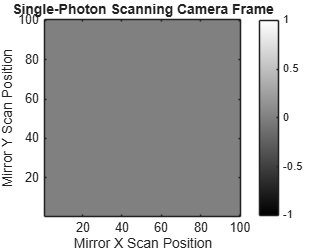



%% ============================================================
% 6. DISPLAY SPC FRAME
% ============================================================

figure;

imagesc(SPC_frame);

axis image;
set(gca,'YDir','normal');

colormap(gray);
colorbar;

xlabel('Mirror X Scan Position');
ylabel('Mirror Y Scan Position');

title('Single-Photon Scanning Camera Frame');



%% ============================================================
% 7. DISPLAY BASIC INFORMATION
% ============================================================

fprintf('\n');
fprintf('============================================\n');

fprintf('TASK 5 - SINGLE-PHOTON SCANNING CAMERA\n');

TASK 5 - SINGLE-PHOTON SCANNING CAMERA


fprintf('============================================\n');


fprintf('Telescope focal length: %.0f mm\n', ...
    focalLength);

Telescope focal length: 6459 mm



fprintf('Fibre diameter: %.1f micrometres\n', ...
    fibreSize * 1000);

Fibre diameter: 4.2 micrometres



fprintf('SPC angular sampling size: %.4f arcsec\n', ...
    SPC_FOV_arcsec);

SPC angular sampling size: 0.1341 arcsec



fprintf('Star-map / scan pixel scale: %.4f arcsec/pixel\n', ...
    STAR_PIXEL_SIZE_arcsec);

Star-map / scan pixel scale: 0.1341 arcsec/pixel



fprintf('Scan positions: %d x %d\n', ...
    MAP_WIDTH, MAP_HEIGHT);

Scan positions: 100 x 100



fprintf('============================================\n');



%% ============================================================
% END OF TASK 5 SCRIPT
% ============================================================
%
% NEXT STEPS:
%
% 1. Insert MR-E-3 mirror movement code
% 2. Determine mirror settling time
% 3. Insert SPCM / NI 6553 photon-count acquisition
% 4. Determine suitable integration time
% 5. Run a real scan
% 6. Store photon counts at every mirror position
% 7. Reconstruct the SPC frame
%
% ============================================================
